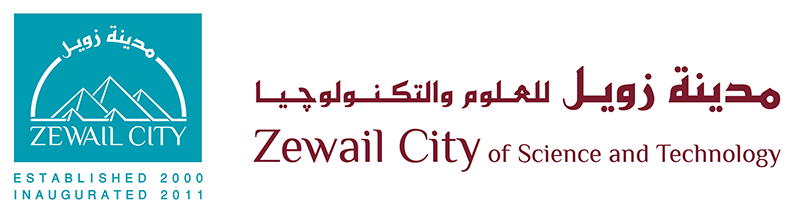

# **                                          Report 3 Math 404**

**Testing the first 3 methods:**

- **The Fibonacci method.**

- **The golden section method.**

- **The quadratic interpolation method.**

The rest of the code is implemented using python to be easier to get grad a function and hessian using grad and hessian built in functions

Function = @(x) 0.65 - 0.75 / (1 + x^2) - 0.65 * x * atan(1 / x);

Fibonacci = Fibonacci_Method(0, 3,Function,0.001);
fprintf('Fibonacci method Solution is: %f\n', Fibonacci);

Fibonacci method Solution is: 0.480488


fprintf('---------------------------------------------------\n');

---------------------------------------------------


Golden = Golden_section(0, 3,Function,0.001);
fprintf('Golden section Solution is: %f\n', Golden);

Golden section Solution is: 0.480679


fprintf('---------------------------------------------------\n');

---------------------------------------------------


quad = quadratic(Function,0.0001);
fprintf('Quadratic Solution is: %f\n', quad);

Quadratic Solution is: 0.498697


fprintf('---------------------------------------------------\n');

---------------------------------------------------


- **The Fibonacci method.**

**The Fibonacci function takes the objective function that needs to be minimized and an interval [a,b] and returns the minimum point.**

function Solution=Fibonacci_Method(a, b,Function, error)
          %%%%%%
% Function:input function
% a the starting point of the interval
% b the ending point of the interval
% error 
          %%%%%%

    %Default error if error not provided 
    if nargin < 4
        error = 0.001;
    end
    %compute Fibonacci numbers
    fibonacci = @(i) Recursive_fibonacci(i);
    number_of_points=(b-a)/error; 
    % Find the index of that Fibonacci number
    for i = 1:number_of_points
        fibonacci_number = fibonacci(i);
        if fibonacci_number >= number_of_points
           break; 
        end
    end
    i = i + 1;
    for j=1:(i-1)
        %Let L0 be the initial interval of uncertainty defined by a≤x≤b 
        L0 = b - a; 
        r1=fibonacci(i-j-1)/fibonacci(i-j+1);
        x1=a+r1*L0;
        x2=b-r1*L0;
        if Function(x2)<Function(x1)
            a=x1;
        else
            b=x2;
        end
    end
    Solution=(a+b)/2;
end
function febo=Recursive_fibonacci(i)
    if i==1
        febo=1;
    elseif i==0
        febo=0;
    else
        febo=Recursive_fibonacci(i-1)+Recursive_fibonacci(i-2);
    end
end  

- **The golden section method.**

function Solution = Golden_section(a, b, Function, error, L0, x1, x2, func_x1, func_x2)
          %%%%%%
% Function:input function
% a the starting point of the interval
% b the ending point of the interval
% error 
          %%%%%%

    golden_ratio = 0.618;

    % Default values for parameters
    if nargin < 5 || isempty(L0)
        L0 = b - a;
    end
    if nargin < 4 || isempty(error)
        error = 0.001;
    end
    if nargin < 8 || isempty(func_x1)||x1==0
        x1 = b - golden_ratio * L0;
        func_x1 = Function(x1);
    end
    if nargin < 9 || isempty(func_x2)||x2==0
        x2 = a + golden_ratio * L0;
        func_x2 = Function(x2);
    end
    %fprintf('L0 is %f\n error is%f\n', L0,error);
    %fprintf('x1 is %f\n x2 is%f\n', x1,x2);
    %fprintf('fx1 is %f\n fx2 is%f\n', func_x1,func_x2);
    %fprintf('---------------------------------------------------');
    if L0 <= error
        %fprintf('a is %f\n b is%f\n', a,b);
        Solution = (a + b) / 2;
        return;
    end

    if func_x1 < func_x2
        %update parameters
        b=x2;
        L0=L0*golden_ratio;
        x2=x1;
        func_x2=func_x1;
        x1=0;
        func_x1=0;
        %calling function again
        Solution = Golden_section(a, b, Function, error, L0, x1, x2, func_x1, func_x2);
    else
        %update parameters
        a=x1;
        L0=L0*golden_ratio;
        x1=x2;
        func_x1=func_x2;
        x2=0;
        func_x2=0;
        %calling function again
        Solution = Golden_section(a, b, Function, error, L0, x1, x2, func_x1, func_x2);
    end
end


- **The quadratic interpolation method.**

function x = quadratic(Function, t, error)
    % Quadratic Interpolation Method for minimizing a unimodal function.
    % INPUTS:
    %   Function: The unimodal function to minimize.
    %   t: Initial step size.
    %   error: Tolerance for convergence.
    % OUTPUT:
    %   x: Approximate location of the minimum of the function.

    % Default error if not provided
    if nargin < 3
        error = 1e-3;
    end

    h = inf;
    f = 1;
    i = 0;

    while abs((h-f)/f) > error
        % Initialization of points A, B, and C for quadratic interpolation
        if i==0
            A=0;
            B=t;
            C=2*t;
        else
             % Adjust points based on lambda_star and function values
            if lambda_star>B && f<fb
                A=B;
                B=lambda_star;
            elseif lambda_star<B && f>fb
                A=lambda_star;
            elseif lambda_star<B && f<fb
                B=lambda_star;
            elseif lambda_star>B && f>fb
                C=lambda_star;
            end
        end
        % Evaluate the function at points A, B, and C
        fa = Function(A);
        fb = Function(B);
        fc = Function(C);

        % Special handling for the first iteration
        if i == 0
            f1=Function(t);
             % Refitting scheme for the initial points
            if f1>fa
                fc=f1;
                lambda_star=(4*fb-3*fa-fc)/(4*fb-2*fc-2*fa);
                lambda_star=lambda_star*(t/2);
            end

            while f1<=fa
                fb=f1;
                f2=Function(2 * t);
                if f2>f1
                    fc=f2;
                    lambda_star=(4*fb-3*fa-fc)/(4*fb-2*fc-2*fa);
                    lambda_star=lambda_star*t;
                    break;
                else
                    f1=f2;
                    t=2*t;
                end
            end
            % Re-initialize A, B, and C after the refitting
            A=0;
            B=t;
            C=2*t;
        end
        % Denominator for calculating coefficients a, b, and c
        value=(A-B)*(B-C)*(C-A);
        if value == 0
            break;
        end

        % Calculate coefficients a, b, and c for the quadratic model
        a=(fa*B*C*(C-B)+fb*C*A*(A-C)+fc*A*B*(B-A))/value;
        b=(fa*(B^2-C^2)+fb*(C^2-A^2)+fc*(A^2-B^2))/value;
        c=-(fa*(B-C)+fb*(C-A)+fc*(A-B))/value;

         % Update lambda_star for the next iteration
        if i
            % Break if c is close to zero to avoid division by zero
            if abs(c)<1e-10
                break;
            end
            lambda_star=(-b)/(2*c);
        end

        % Evaluate the quadratic model at lambda_star
        h=a+b*lambda_star+c*(lambda_star^2);
        % Evaluate the true function at lambda_star
        f=Function(lambda_star);
        i=i+1;
    end
    x = lambda_star;
end


**Methods implemented by python:**

- **The cubic interpolation method.**

- **Fletcher Reeves CG Method**

- **Marquardt Method**

- **Quasi-Newton Method (BFGS)**